# Analize resulds of 3D FD modelling

## Introduction

Check results of FD Heidimod program

**Author**: Abakumov Ivan

Freie Universität Berlin

**Publication date**: 21th September 2017

**E-mail**: [abakumov_ivan@mail.ru](mailto:abakumov_ivan@mail.ru)

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Set parameters of FD modeling

folder = [mlibfolder '/Examples/Heidimod/s90900/'];
nts = 20;                   % number of time samples of the wavelet
nrec = 8;                   % number of receivers

## Read files 

wavelet

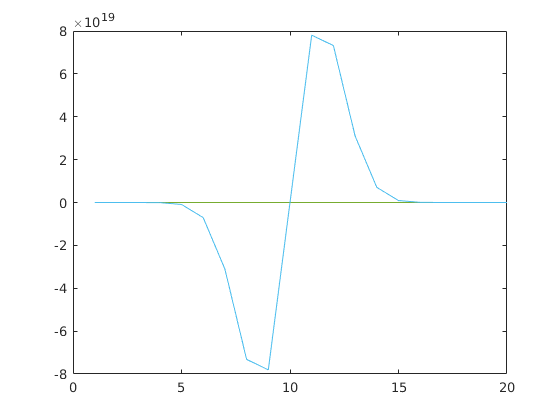

fid = fopen([folder 'wavelet'],'r');
data = fread(fid, inf, 'single', 'ieee-be');
fclose(fid);
data=reshape(data,[nts,6,1]);
plot(data(:,:))

clear data

source positions

fid = fopen([folder 'slocation'],'r');
sloc = fread(fid, inf, 'single', 'ieee-be');
fclose(fid);

receiver positions

fid = fopen([folder 'geoloc'],'r');
gloc = fread(fid, inf, 'single', 'ieee-be');
fclose(fid);
gloc  = reshape(gloc,[3,nrec]);

moduli

fid = fopen([folder 'moduli'],'r');
moduli = fread(fid, inf, 'single', 'ieee-be');
fclose(fid);